%Week 13 tutorial questions
%clearing crap
clear all

syms t a w real %declaring symbolic variables

assumeAlso (a>0)

%question 1
f1(t) = piecewise(t<=0, exp(a*t), t>0, exp(-a*t))

$$f1(t) = \left\{ \begin{array}{cl} {\mathrm{e}}^{a\,t} & \text{ if }t\leq 0\\ {\mathrm{e}}^{-a\,t} & \text{ if }0<t \end{array}\right.$$


%plotting example
f1plot(t) = subs(f1(t),a,1)

$$f1plot(t) = \left\{ \begin{array}{cl} {\mathrm{e}}^{t} & \text{ if }t\leq 0\\ {\mathrm{e}}^{-t} & \text{ if }0<t \end{array}\right.$$

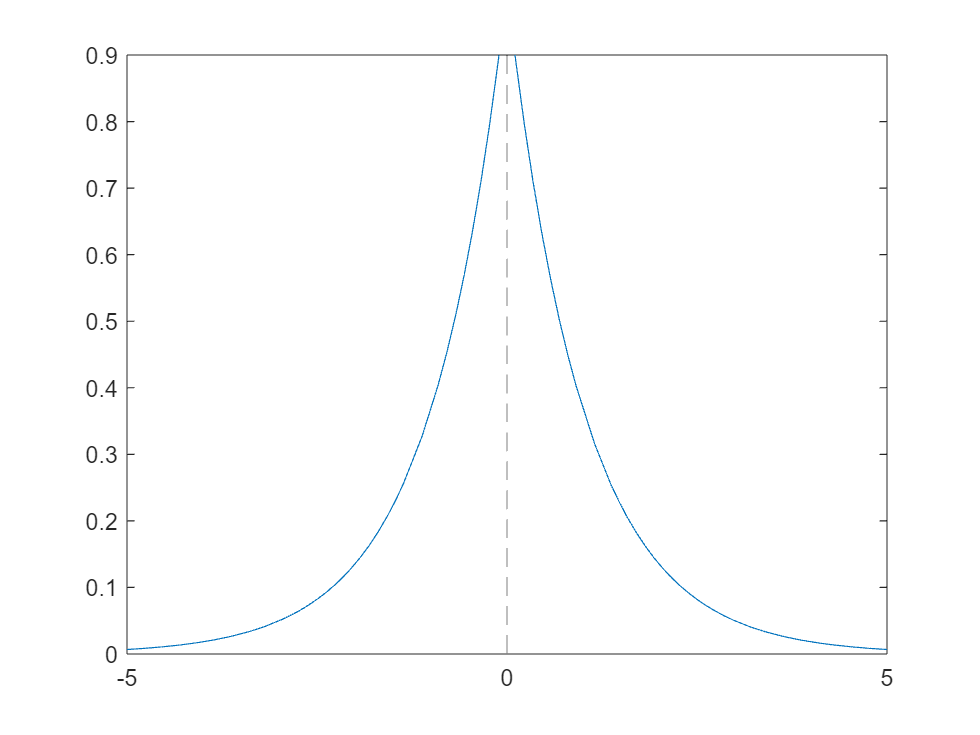

%plotting with a=1
fplot(f1plot)

%performing fourier
%G1(w) = 1/sqrt(2*sym(pi))*fourier(f1(t),w)
G1(w) = simplify((1/sqrt(2*sym(pi))) * int(f1(t)*exp(1i*w*t),t,[-inf inf]))

$$G1(w) = \frac{\sqrt{2}\,a}{\sqrt{\pi }\,\left(a^{2}+w^{2}\right)}$$